# 7. Computer Vision Application - Object Detection(1/2)

load petGT.mat

### Peek into the data

Investigate `'petGT'` table.

petGT

petGT = 432×6 table
           imageFilename                  Ginny                 Lucy                Madeline                 Kima                  Susan      
    ____________________________    _________________    __________________    ___________________    ___________________    _________________

    {'Madeline/Madeline135.jpg'}    {0×0 double     }    {0×0 double      }    {[ 163 156 110 92]}    {0×0 double       }    {0×0 double     }
    {'Lucy/Lucy120.jpg'        }    {0×0 double     }    {[65 304 143 145]}    {0×0 double       }    {0×0 double       }    {0×0 double     }
    {'Kima/Kima409.jpg'        }    {0×0 double     }    {0×0 double      }    {0×0 double       }    {[424 173 168 173]}    {0×0 double     }
    {'Madeline/Madeline242.jpg'}    {0×0 double     }    {0×0 double      }    {[ 156 77 256 287]}    {0×0 double       }    {0×0 double     }
    {'Kima/Kima360.jpg'        }    {0×0 double     }    {0×0 double      }    {0×0 double       }    {[  326 170 39 39]}

Read the first image in the table and display.

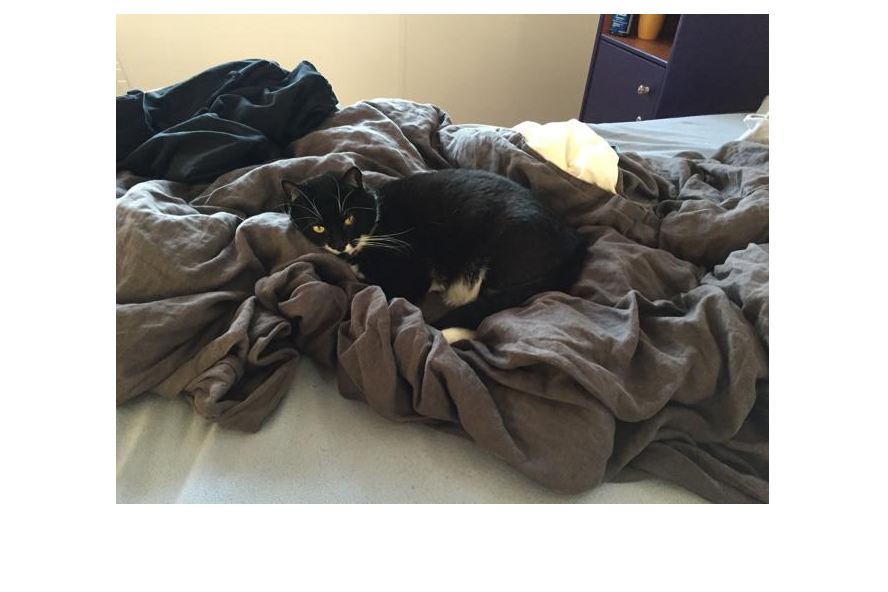

image1 = imread(petGT.imageFilename{1});
imshow(image1)

petGT.imageFilename

ans = 432×1 cell 배열
    {'Madeline/Madeline135.jpg'}
    {'Lucy/Lucy120.jpg'        }
    {'Kima/Kima409.jpg'        }
    {'Madeline/Madeline242.jpg'}
    {'Kima/Kima360.jpg'        }
    {'Susan/Susan286.jpg'      }
    {'Madeline/Madeline188.jpg'}
    {'Kima/Kima391.jpg'        }
    {'Kima/Kima370.jpg'        }
    {'Ginny/Ginny75.jpg'       }
    {'Kima/Kima389.jpg'        }
    {'Kima/Kima346.jpg'        }
    {'Kima/Kima368.jpg'        }
    {'Kima/Kima417.jpg'        }
    {'Madeline/Madeline196.jpg'}
    {'Madeline/Madeline198.jpg'}
    {'Susan/Susan306.jpg'      }
    {'Susan/Susan307.jpg'      }
    {'Madeline/Madeline237.jpg'}
    {'Susan/Susan302.jpg'      }
    {'Ginny/Ginny87.jpg'       }
    {'Kima/Kima373.jpg'        }
    {'Madeline/Madeline231.jpg'}
    {'Madeline/Madeline149.jpg'}
    {'Madeline/Madeline211.jpg'}
    {'Kima/Kima413.jpg'        }
    {'Ginny/Ginny2.jpg'        }
    {'Madeline/Madeline203.jpg'}
    {'Kima/Kima349.jpg'        }
    {'Madeline/Madeline

## Inserting Annotation(Bounding box + Label) into Image

The remaining variables in `'petGT'` table are the bounding boxes for each pet. You can extract a bounding box using the same pattern as the filenames. You should still use brackets({ }) to extract the bounding box.

'petGT' 테이블의 나머지 변수는 각 애완동물에 대한 경계 상자입니다. 파일 이름과 동일한 패턴을 사용하여 경계 상자를 추출할 수 있습니다. 경계 상자를 추출하려면 대괄호({ })를 사용해야 합니다.

annotationLabel1 = "Madeline"

annotationLabel1 = "Madeline"

bbox1 = petGT.Madeline{1}

bbox1 =    163   156   110    92


To view the image along with its label, you can add the bounding box to the image using `insertObjectAnnotation` function

라벨과 함께 이미지를 보려면 insertObjectAnnotation 함수를 사용하여 이미지에 경계 상자를 추가하면 됩니다.

labeledIm1 = insertObjectAnnotation(image1,"rectangle",...
    bbox1,annotationLabel1) %셀 형태로 들어갔다.

labeledIm1 = 490×653×3 uint8 배열
labeledIm1(:,:,1) =

   246   246   246   246   246   246   246   246   245   245   245   245   245   245   245   245   244   244   244   244   244   244   244   244   244   244   244   244   244   244   244   244   244   244   244   245   245   246   246   246   246   246   246   246   246   246   246   246   245   245   245   245   245   245   245   245   245   245   245   245   245   245   245   245   247   247   247   247   247   247   247   247   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   246   247   247   247   247   247   247   247   247   248   248   248   248   248   248   248   248   249   249   249   249   249   249   249   249   250   250   250   250   250   250   250   250   250   250   250   250   250   250   250   250   250   250   250   249   249   248   248   248   249   249   249   249   249   249   249   249   248   248   248   249   249   250   250   250   250   250   250   250   250   25

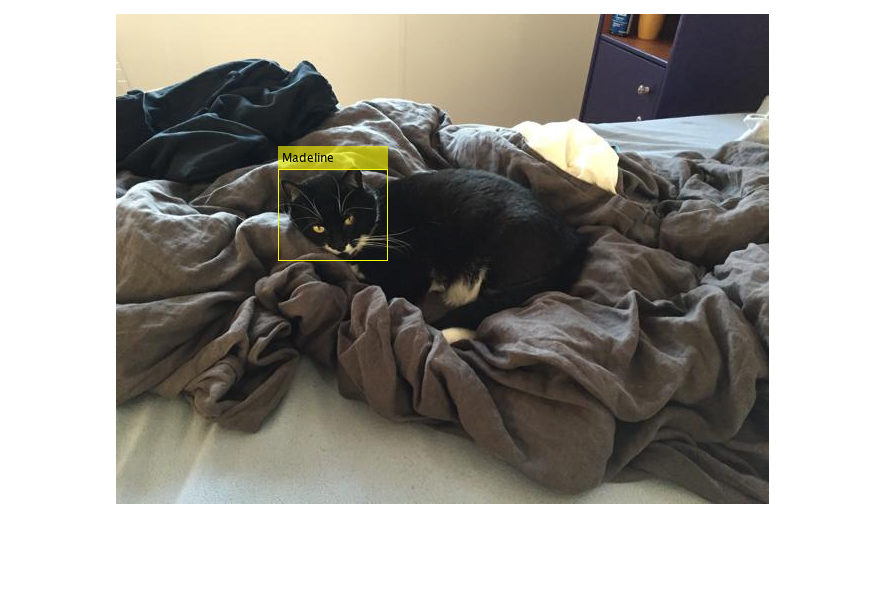

imshow(labeledIm1)

## Preprocessing Ground Truth

For object detection, every image has a labeled bounding box. If you preprocess your images, you need to be careful to update the bounding boxes accordingly.

Many object detectors don't require images to be the same size, but scaling your training data to a consistent size can help avoid issues during training. Since the bounding boxes are stored with pixel locations, you need to scale the bounding boxes if you scale your images.

객체 감지를 위해 모든 이미지에는 라벨이 지정된 경계 상자가 있습니다. 이미지를 전처리하는 경우 그에 따라 경계 상자를 업데이트하도록 주의해야 합니다.

많은 객체 감지기에는 이미지 크기가 동일할 필요가 없지만 훈련 데이터를 일관된 크기로 조정하면 훈련 중 문제를 방지하는 데 도움이 될 수 있습니다. 경계 상자는 픽셀 위치와 함께 저장되므로 이미지 크기를 조정하려면 경계 상자의 크기를 조정해야 합니다.

###     Create an image datastore and a box label datastore

imDS = imageDatastore(petGT.imageFilename)

imDS =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../Documents/MATLAB/인공지능/Week2/petImages/Madeline/Madeline135.jpg';
                              ' .../Documents/MATLAB/인공지능/Week2/petImages/Lucy/Lucy120.jpg';
                              ' .../Documents/MATLAB/인공지능/Week2/petImages/Kima/Kima409.jpg'
                               ... and 429 more
                              }
                     Folders: {
                              ' .../jeongseong-yun/Documents/MATLAB/인공지능/Week2/petImages/Madeline';
                              ' .../jeongseong-yun/Documents/MATLAB/인공지능/Week2/petImages/Lucy';
                              ' .../jeongseong-yun/Documents/MATLAB/인공지능/Week2/petImages/Kima'
                               ... and 2 more
                              }
    AlternateFileSystemRoots: {}
 

boxDS = boxLabelDatastore(petGT(:,2:end))

boxDS =   boxLabelDatastore - 속성 있음:

    LabelData: 
               432x2 cell array
               
               {[ 163 156 110 92]}    {[Madeline]}
               {[ 65 304 143 145]}    {[Lucy    ]}
               {[424 173 168 173]}    {[Kima    ]}
               
                ... and 429 more rows
    ReadSize: 1


% petGT{:,2:end}

###     Combine datastores 

combinedDS = combine(imDS,boxDS)

combinedDS =   CombinedDatastore - 속성 있음:

      UnderlyingDatastores: {[1×1 matlab.io.datastore.ImageDatastore]  [1×1 boxLabelDatastore]}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]


###     Resize images and bounding boxes

resizedDS = transform(combinedDS, @scaleGT)

resizedDS =   TransformedDatastore - 속성 있음:

      UnderlyingDatastores: {matlab.io.datastore.CombinedDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
                Transforms: {@scaleGT}
               IncludeInfo: 0


###     Preview the resized data

    To view a preprocessed ground truth, you can preview the first image in the datastore

전처리된 정답을 보려면 데이터 저장소의 첫 번째 이미지를 미리 보면 됩니다.

newGT = preview(resizedDS)

newGT = 1×3 cell 배열
    {224×224×3 uint8}    {[55.9142 71.3143 37.7335 42.0571]}    {[Madeline]}


resizedData = insertObjectAnnotation(newGT{1}, "rectangle",...
    newGT{2},newGT{3})

resizedData = 224×224×3 uint8 배열
resizedData(:,:,1) =

   246   246   246   245   245   244   244   244   244   244   244   244   245   246   246   246   245   245   245   245   245   245   247   247   247   246   246   246   246   246   247   247   247   248   248   248   249   249   250   250   250   250   250   250   250   249   248   249   249   248   249   250   250   250   250   250   250   250   249   249   249   249   249   248   248   248   248   248   248   248   248   247   247   247   246   246   246   245   245   245   244   242   241   241   241   241   240   239   238   238   238   238   236   235   234   233   233   228   228   226   226   225   226   224   223   221   220   219   218   217   218   216   216   216   214   214   213   212   210   210   210   210   208   208   208   206   208   207   206   205   204   203   202   200   200   200   198   199   196   193   190   188   186   187   185   184   183   182   183   182   181   182   181   180   180   178   178   

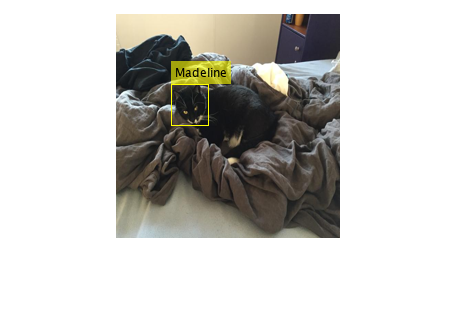

%newGT{1} -> array, newGT(1) -> cell
imshow(resizedData)

### Support function

`scaleGT` resizes images to `targetSize`. It also uses the same scale to resize the corresponding bounding boxes.

scaleGT는 이미지 크기를 targetSize로 조정합니다. 또한 동일한 배율을 사용하여 해당 경계 상자의 크기를 조정합니다.

function data = scaleGT(data)  
    targetSize = [224 224];
    % data{1} is the image
    scale = targetSize./size(data{1},[1 2]);
    data{1} = imresize(data{1},targetSize);
    % data{2} is the bounding box
    data{2} = bboxresize(data{2},scale);
end